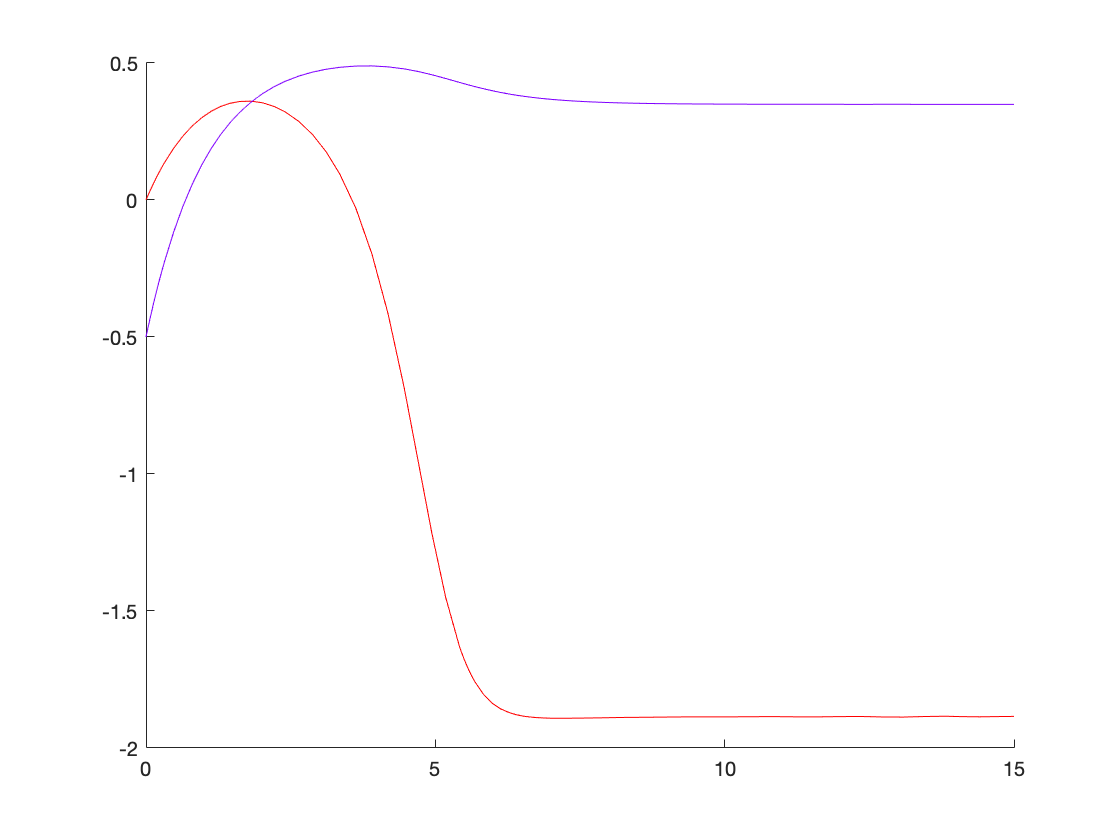

a = 0.5;
b = 1;
e = 0.08;

dvdt =@(v,w) v - 1/3*v^3 - w; 
dwdt =@(v,w) e*v + a - b*w;

x_0 = [0,-0.5];

[T, X] = ode45(@(t,x)[dvdt(x(1),x(2));dwdt(x(1),x(2))], [0,15], x_0 );

figure; hold on;
plot(T,X(:,1),'-r');
plot(T,X(:,2),'-', 'color', [0.5 0 1]);

I0 = 10;
tStart = 40;
tStop = 47;

a = 1;
b = 1;
e = 0.08;
D = 0.9;

x_0 = [-0.5,zeros(1,9),1,zeros(1,9)];
tspan = [0,100];

[T, X] = ode45(@(T,y) odefcn(y,e,a,b,D,T,I0,tStart,tStop), tspan, x_0 );

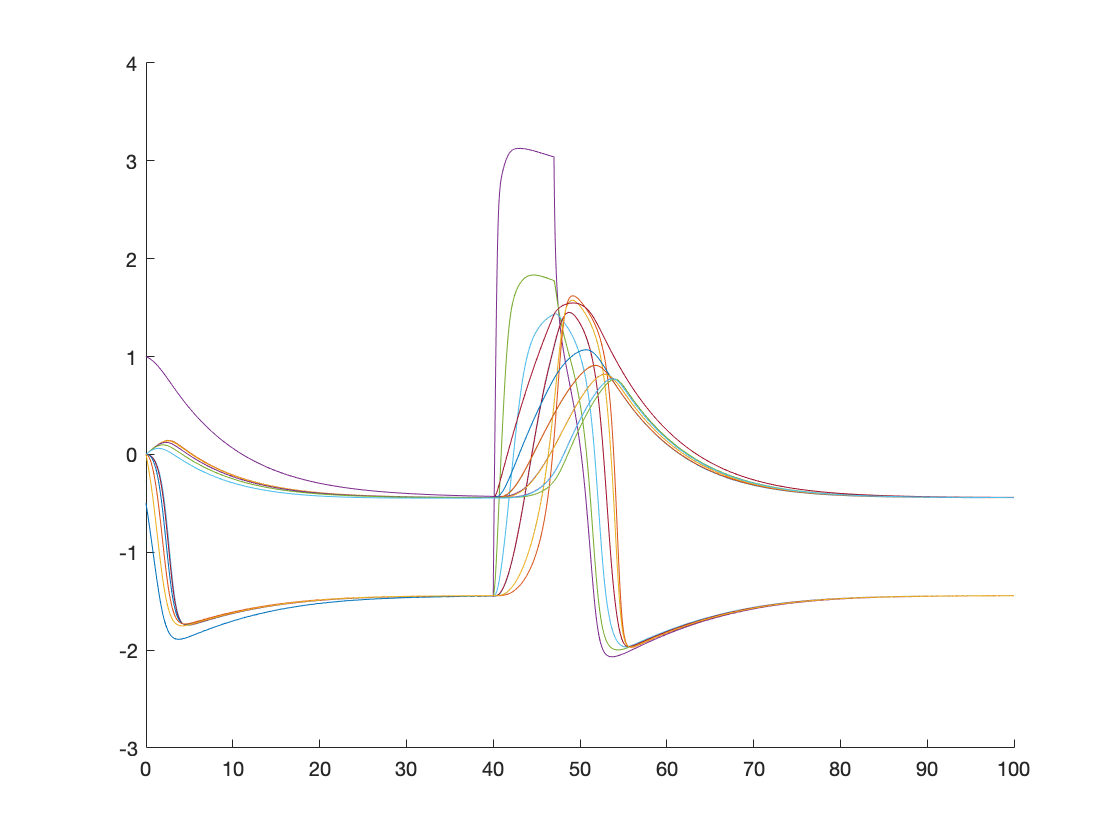

figure; hold on;
plot(T,X);

%xlim([30 60])
%legend